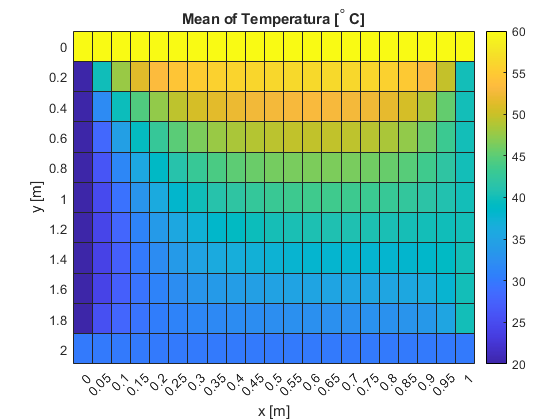

clear,clc,close all
L=1;
W=2;
f=@(x,y) sin(x)+cos(y);
dx=0.05;
dy=0.2;
x=0:dx:L;
y=0:dy:W;

iterations=0;
gradient=1;
convergence=0.01;

A=ones(length(y),length(x));
init=25;
A=A*init;
A(1:end,1)=20; % lewy
A(1:end,end)=40; % prawy
A(1,1:end)=60; % gora
A(end,1:end)=30; % dol
tic
while gradient>convergence
    B(1:length(y),1)=A(1:end,1); % le
    B(1:length(y),length(x))=A(1:end,end); % prawy
    B(1,1:length(x))=A(1,1:end); % gora
    B(length(y),1:length(x))=A(end,1:end); % dol
    for i=2:length(y)-1
        for j=2:length(x)-1
            B(i,j)=0.25*(B(i-1,j)+A(i+1,j)+B(i,j-1)+A(i,j+1)-dx*dy*f(x(j),y(i)));
            
        end
    end
    o=1;
    iterations=iterations+1;
    change=abs(A-B);
    gradient=max(max(change));
    diff(iterations,1:2)=[iterations,gradient];
    A=B;
    for k=1:length(y)
        for l=1:length(x)
            x_final(o,1)=x(l);
            y_final(o,1)=y(k);
            u_final(o,1)=A(k,l);
            o=o+1;
        end
    end
    t=table([x_final],[y_final],[u_final]);
    t = renamevars(t,["x_final","y_final","u_final"], ...
        ["x [m]","y [m]","Temperatura [^{\circ} C]"]);
    h = heatmap(t,'x [m]','y [m]','ColorVariable', ...
        'Temperatura [^{\circ} C]','Colormap',parula);
    drawnow
end

toc

Elapsed time is 67.636756 seconds.


fprintf('Liczba iteracji=%0.1d ',iterations)

Liczba iteracji=83 

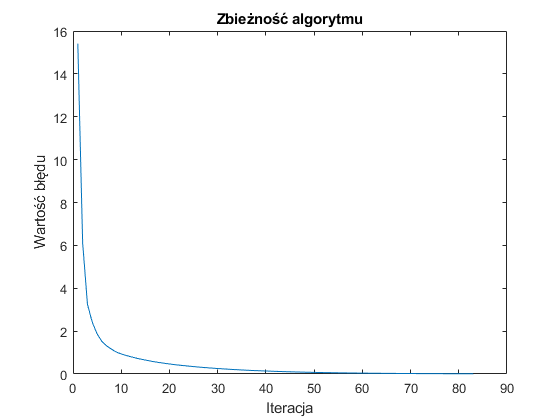

plot(diff(1:end,1),diff(1:end,2))
title('Zbieżność algorytmu')
xlabel('Iteracja')
ylabel('Wartość błędu')